# Modèle 3 degré de liberté du bateau

## Objectif

Le but est de reconstruire les signaux manquants du bateau qui sont l'angle de cap $\psi$ et la composante latérale de vitesse dans le repère du bateau $v$.

## Signaux à dispostion

Les différents signaux qui sont mesurés, et qui sont à notre disposition pour retrouver les signaux manquants, cont les suivants:

- La position et la vitesse dans le repère fixe obtenue grâce au capteur GPS: $x,y,v_x ,v_y$

- La vitesse longitudinale dans le repère du bateau mesurée par le loch: $u$

- Les accélérations dans le repère du bateau obtenues grâce à la centrale inertielle: $a_x ,a_y$

- La vitesse angulaire de lacet mesurée par la centrale inertielle: $r$

load('data2.mat')
load('bruit_signaux_rééls.mat')
clear('legend')

T_final = 600;	       
h = 0.05; 
t = 0:h:T_final;  

u     = simdata(:,1); 
v     = simdata(:,2);          
r     = (simdata(:,4));
psi   = simdata(:,6);
x     = simdata(:,9);
y     = simdata(:,10);

vx = u.*cos(psi)-v.*sin(psi);
vy = u.*sin(psi)+v.*cos(psi);

## Relations existante entre les signaux

Une relation simple entre un certain nombre de signaux est donné par une équation de chagement de base:


$$\left\lbrack \begin{array}{c}
u=v_x \;\cos \left(\psi \right)+v_y \;\sin \left(\psi \right)\\
v={-v}_x \;\sin \left(\psi \right)+v_y \;\cos \left(\psi \right)
\end{array}\right\rbrack$$


## Inversions de modèle

### Première version

        
$$\left\lbrack \begin{array}{c}
v=-\sqrt{v_x^2 +v_y^2 -u^2 }\\
\psi =\tan \left(\frac{v_y }{v_x }\right)-\tan \left(\frac{v}{u}\right)
\end{array}\right\rbrack$$


Dans cette version, on utilise la norme de la vitesse pour retrouver $v$. Ensuite, on l'utilise pour reconstruire $\psi$.

La difficulté avec ces équations réside dans le fait de déterminer le signe de v. (semble dépendre de $r$)

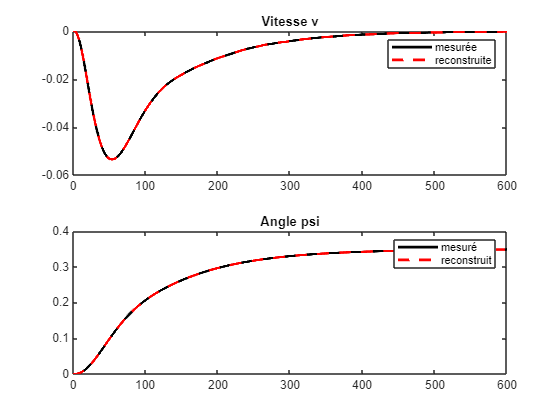

%% Modèle 3ddl

vr = -sqrt(abs(vx.^2+vy.^2-u.^2));
psir = atan2(vy,vx)-atan2(vr,u);

%% Display

figure(10),
subplot(211),
plot(t,v,'k',t,vr,'--r',LineWidth=2)
title('Vitesse v')
legend('mesurée','reconstruite')

subplot(212)
plot(t,psi,'k',t,psir,'--r',LineWidth=2)
title('Angle psi')
legend('mesuré','reconstruit')

Les siganux sont bien reconstruits, maintenant on ajoute du bruit de mesure:

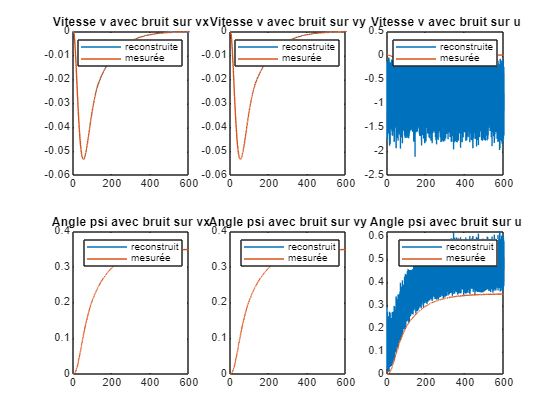

vx_b = vx + 1e-8*randn(12001,1);
vy_b = vy + 1e-8*randn(12001,1);
u_b = u + sqrt(var_bruit(3))*randn(12001,1);

%% Influence du bruit

vr1 = -sqrt(abs(vx_b.^2+vy.^2-u.^2));
psir1 = atan2(vy,vx_b)-atan2(vr1,u);

vr2 = -sqrt(abs(vx.^2+vy_b.^2-u.^2));
psir2 = atan2(vy_b,vx)-atan2(vr2,u);

vr3 = -sqrt(abs(vx.^2+vy.^2-u_b.^2));
psir3 = atan2(vy,vx)-atan2(vr3,u_b);
beta3 = atan2(vr,u_b);

figure(2),
subplot(231),
plot(t,vr1,t,v)
title('Vitesse v avec bruit sur vx')
legend('reconstruite','mesurée')

subplot(234)
plot(t,psir1,t,psi)
title('Angle psi avec bruit sur vx')
legend('reconstruit','mesurée')

subplot(232),
plot(t,vr2,t,v)
title('Vitesse v avec bruit sur vy')
legend('reconstruite','mesurée')

subplot(235)
plot(t,psir2,t,psi)
title('Angle psi avec bruit sur vy')
legend('reconstruit','mesurée')

subplot(233),
plot(t,vr3,t,v)
title('Vitesse v avec bruit sur u')
legend('reconstruite','mesurée')

subplot(236)
plot(t,psir3,t,psir)
title('Angle psi avec bruit sur u')
legend('reconstruit','mesurée')

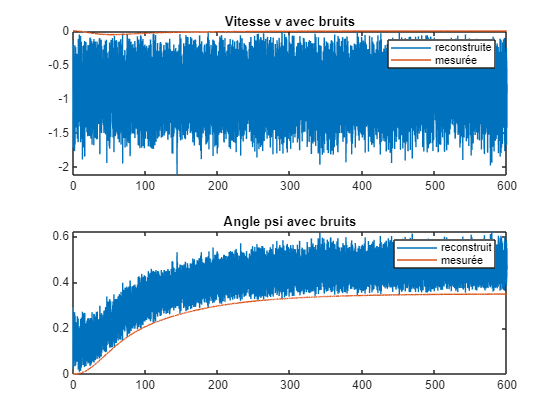


%%

vr4 = -sqrt(abs(vx_b.^2+vy_b.^2-u_b.^2));
psir4 = atan2(vy_b,vx_b)-atan2(vr4,u_b);

figure(4),
subplot(211),
plot(t,vr4,t,v)
title('Vitesse v avec bruits')
legend('reconstruite','mesurée')

subplot(212)
plot(t,psir4,t,psi)
title('Angle psi avec bruits')
legend('reconstruit','mesurée')

On constate une grande influence du bruit de mesure sur ce modèle.

### Deuxième version


$$\left\lbrack \begin{array}{c}
\overset{\cdot }{\psi} =r\\
v={-v}_x \;\sin \left(\psi \right)+v_y \;\cos \left(\psi \right)
\end{array}\right\rbrack$$


Dans cette version, on viens intégrer la vitesse angulaire de lacet $r$ qui est aussi la dérivée de l'angle $\psi$. Ensuite, on l'utiliste pour reconstruire $v$ à l'aide de $v_x \;$et $v_y$.

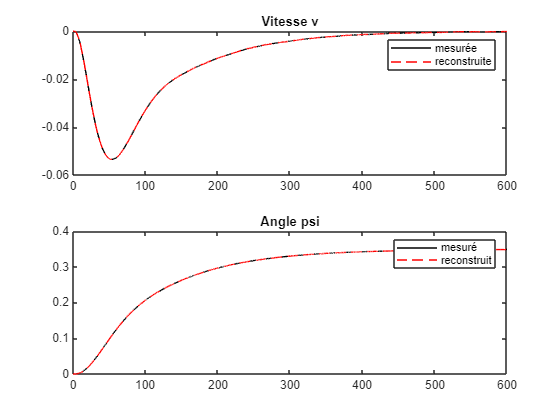

%% Modèle 3ddl

psir = zeros(length(t),1);
for i =2:length(t)
    psir(i,1) = euler2(r(i-1),psir(i-1,1),h);
end
vr = vy.*cos(psir(:,1)) - vx.*sin(psir(:,1));

%% Display

figure(1),
subplot(211),
plot(t,v,'k',t,vr,'--r')
title('Vitesse v')
legend('mesurée','reconstruite')

subplot(212)
plot(t,psi,'k',t,psir,'--r')
title('Angle psi')
legend('mesuré','reconstruit')

Les siganux sont bien reconstruits, maintenant on ajoute du bruit de mesure:

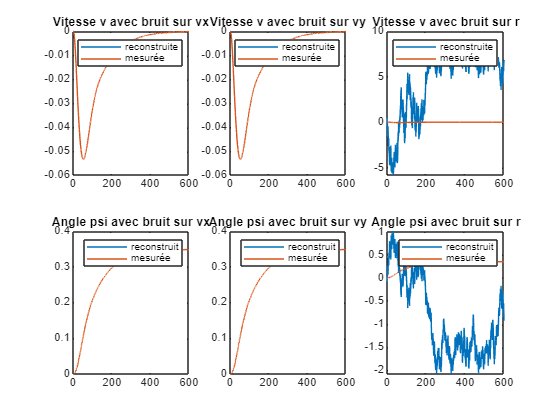

r_b = r + sqrt(var_bruit(6))*randn(12001,1);
%% Influence du bruit

psir1 = psir;
vr1 = vy.*cos(psir1(:,1)) - vx_b.*sin(psir1(:,1));

psir2 = psir;
vr2 = vy_b.*cos(psir2(:,1)) - vx.*sin(psir2(:,1));

psir3 = zeros(length(t),1);
for i =2:length(t)
    psir3(i,1) = euler2(r_b(i-1),psir3(i-1,1),h);
end
vr3 = vy.*cos(psir3(:,1)) - vx.*sin(psir3(:,1));

figure(2),
subplot(231),
plot(t,vr1,t,v)
title('Vitesse v avec bruit sur vx')
legend('reconstruite','mesurée')

subplot(234)
plot(t,psir1,t,psi)
title('Angle psi avec bruit sur vx')
legend('reconstruit','mesurée')

subplot(232),
plot(t,vr2,t,v)
title('Vitesse v avec bruit sur vy')
legend('reconstruite','mesurée')

subplot(235)
plot(t,psir2,t,psi)
title('Angle psi avec bruit sur vy')
legend('reconstruit','mesurée')

subplot(233),
plot(t,vr3,t,v)
title('Vitesse v avec bruit sur r')
legend('reconstruite','mesurée')

subplot(236)
plot(t,psir3,t,psir)
title('Angle psi avec bruit sur r')
legend('reconstruit','mesurée')

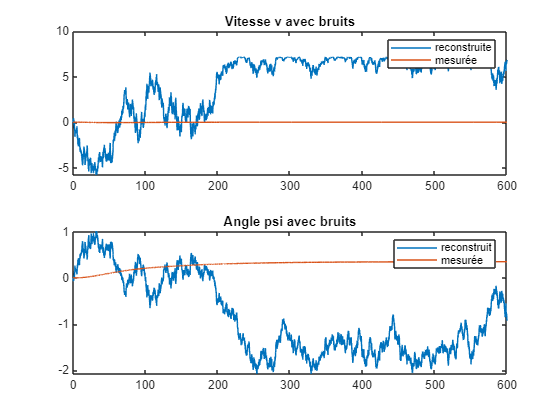


%%

psir4 = psir3;
vr4 =  vy_b.*cos(psir4(:,1)) - vx_b.*sin(psir4(:,1));

figure(4),
subplot(211),
plot(t,vr4,t,v)
title('Vitesse v avec bruits')
legend('reconstruite','mesurée')

subplot(212)
plot(t,psir4,t,psi)
title('Angle psi avec bruits')
legend('reconstruit','mesurée')

On remarque que les bruits de mersure affectent peu la reconstruction de l'angle $\psi$. Ce modèle est moins dépend du bruits de mesure que le précedent.

## Conclusion

Les deux modèles ne sont pas linéaires, une tentaive de linéarisation a été faite afin d'utiliser nos connaissances dans le domaine mais sans résultats probants. 